clc;
clear;
simu="PIL_Arduino_v04";     % Simulink file name

## Simulation Settings

simulate= true; % True: To simulate
Tsim = 5 ;        % Total Simulation length in seconds. 
                        % Set Tsim=Inf to run indefinitely                            
fs=33;              % Sampling Frequency in Hz

xo=[-1 1]';        % Initial System State Condition

Ts=1/fs;            % Sampling Period

## Continuous-Time Linear State-Space Model

x_dot(t) = Ac?x(t)+Bc?x(t) y(t) = Cc?x(t)

n=2;    % Number of System States

Ac=[[1 0];
     [1 1]];
Bc=[1 0]';
Cc=[1 0];
CO = ctrb(Ac,Bc);

if (rank(CO)==2)
    disp('System is Controllable')
else 
    disp('System is NOT Controllable')
    simulate = false;
end

System is Controllable


## Start Simulation

Simulating...


Plotting...


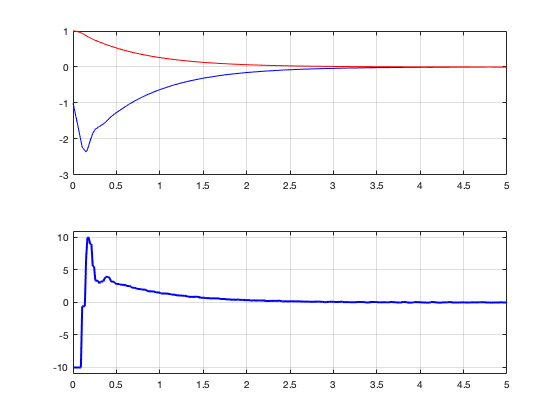

Done!!!


if (simulate)
    open_system(simu);
    disp('Simulating...')
    sim(simu)
    disp('Plotting...')
    
    x1=in(:,1);
    x2=in(:,2);
    u1=out(:,1);
    save('result_data.mat')
    plot_results;
    disp('Done!!!')
    
end